initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.13.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

model = readCbModel('ecoli_core_model.mat')

Each model.subSystems{x} is a character array, and this format is retained.


model = struct with fields:
                      S: [72×95 double]
                   mets: {72×1 cell}
                      b: [72×1 double]
                 csense: [72×1 char]
                   rxns: {95×1 cell}
                     lb: [95×1 double]
                     ub: [95×1 double]
                      c: [95×1 double]
              osenseStr: 'max'
                  genes: {137×1 cell}
                  rules: {95×1 cell}
             metCharges: [72×1 int32]
            metFormulas: {72×1 cell}
               metNames: {72×1 cell}
         metInChIString: {72×1 cell}
              metKEGGID: {72×1 cell}
             metChEBIID: {72×1 cell}
           metPubChemID: {72×1 cell}
                grRules: {95×1 cell}
             rxnGeneMat: [95×137 double]
    rxnConfidenceScores: [95×1 double]
               rxnNames: {95×1 cell}
               rxnNotes: {95×1 cell}
           rxnECNumbers: {95×1 cell}
          rxnReferences: {95×1 cell}
             subSystems: {95×1 cel

A map of this model is shown below (Ecoli core map - Orth-2010.jpg)

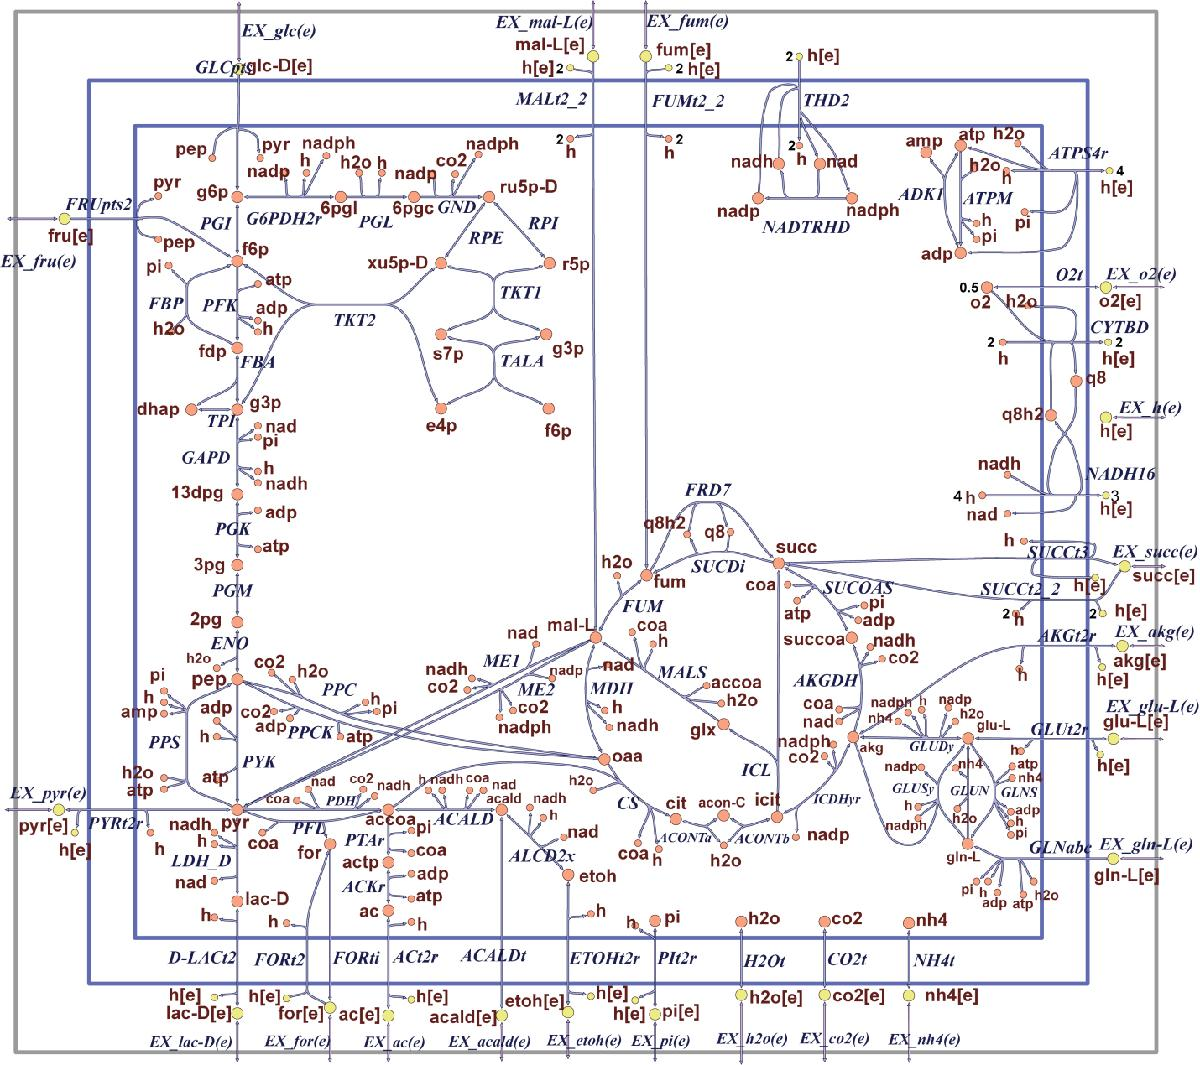

Solving for the fluxes in the model

solution = optimizeCbModel(model)

solution = struct with fields:
    origStatText: []
               f: 0.8739
               v: [95×1 double]
               y: [72×1 double]
               w: [95×1 double]
               s: [72×1 double]
          solver: 'gurobi'
       algorithm: 'default'
            stat: 1
        origStat: 'OPTIMAL'
            time: 0.0060
           basis: [1×1 struct]
          vars_v: []
               x: [95×1 double]


solution

solution = struct with fields:
    origStatText: []
               f: 0.8739
               v: [95×1 double]
               y: [72×1 double]
               w: [95×1 double]
               s: [72×1 double]
          solver: 'gurobi'
       algorithm: 'default'
            stat: 1
        origStat: 'OPTIMAL'
            time: 0.0060
           basis: [1×1 struct]
          vars_v: []
               x: [95×1 double]


printFluxVector(model, solution.x, true)

ACONTa              	       6.007
ACONTb              	       6.007
AKGDH               	       5.064
ATPM                	        8.39
ATPS4r              	       45.51
Biomass_Ecoli_core_N(w/GAM)-Nmet2	      0.8739
CO2t                	      -22.81
CS                  	       6.007
CYTBD               	        43.6
ENO                 	       14.72
EX_co2(e)           	       22.81
EX_glc(e)           	         -10
EX_h2o(e)           	       29.18
EX_h(e)             	       17.53
EX_nh4(e)           	      -4.765
EX_o2(e)            	       -21.8
EX_pi(e)            	      -3.215
FBA                 	       7.477
FUM                 	       5.064
G6PDH2r             	        4.96
GAPD                	       16.02
GLCpts              	          10
GLNS                	      0.2235
GLUDy               	      -4.542
GND                 	        4.96
H2Ot                	      -29.18
ICDHyr              	       6.007
MDH                 	       5.064
NADH16              	       38.53
N

Writing flux for Escher Map

% Create table of flux values
Reactions = model.rxns;
Flux = round(solution.x,3);
T = table(Reactions,Flux,'RowNames',model.rxns);
% Write to CSV file
writetable(T,'escher_flux.csv');

Using the Escher application located at "https://escher.github.io/#/" with the following settings

Filter by organism - All

Map - Core metabolism (e_coli_core)

Model (optional) - e_coli_core

Tool - Builder

After the setting are set right then load the map. Another window should open with the following map

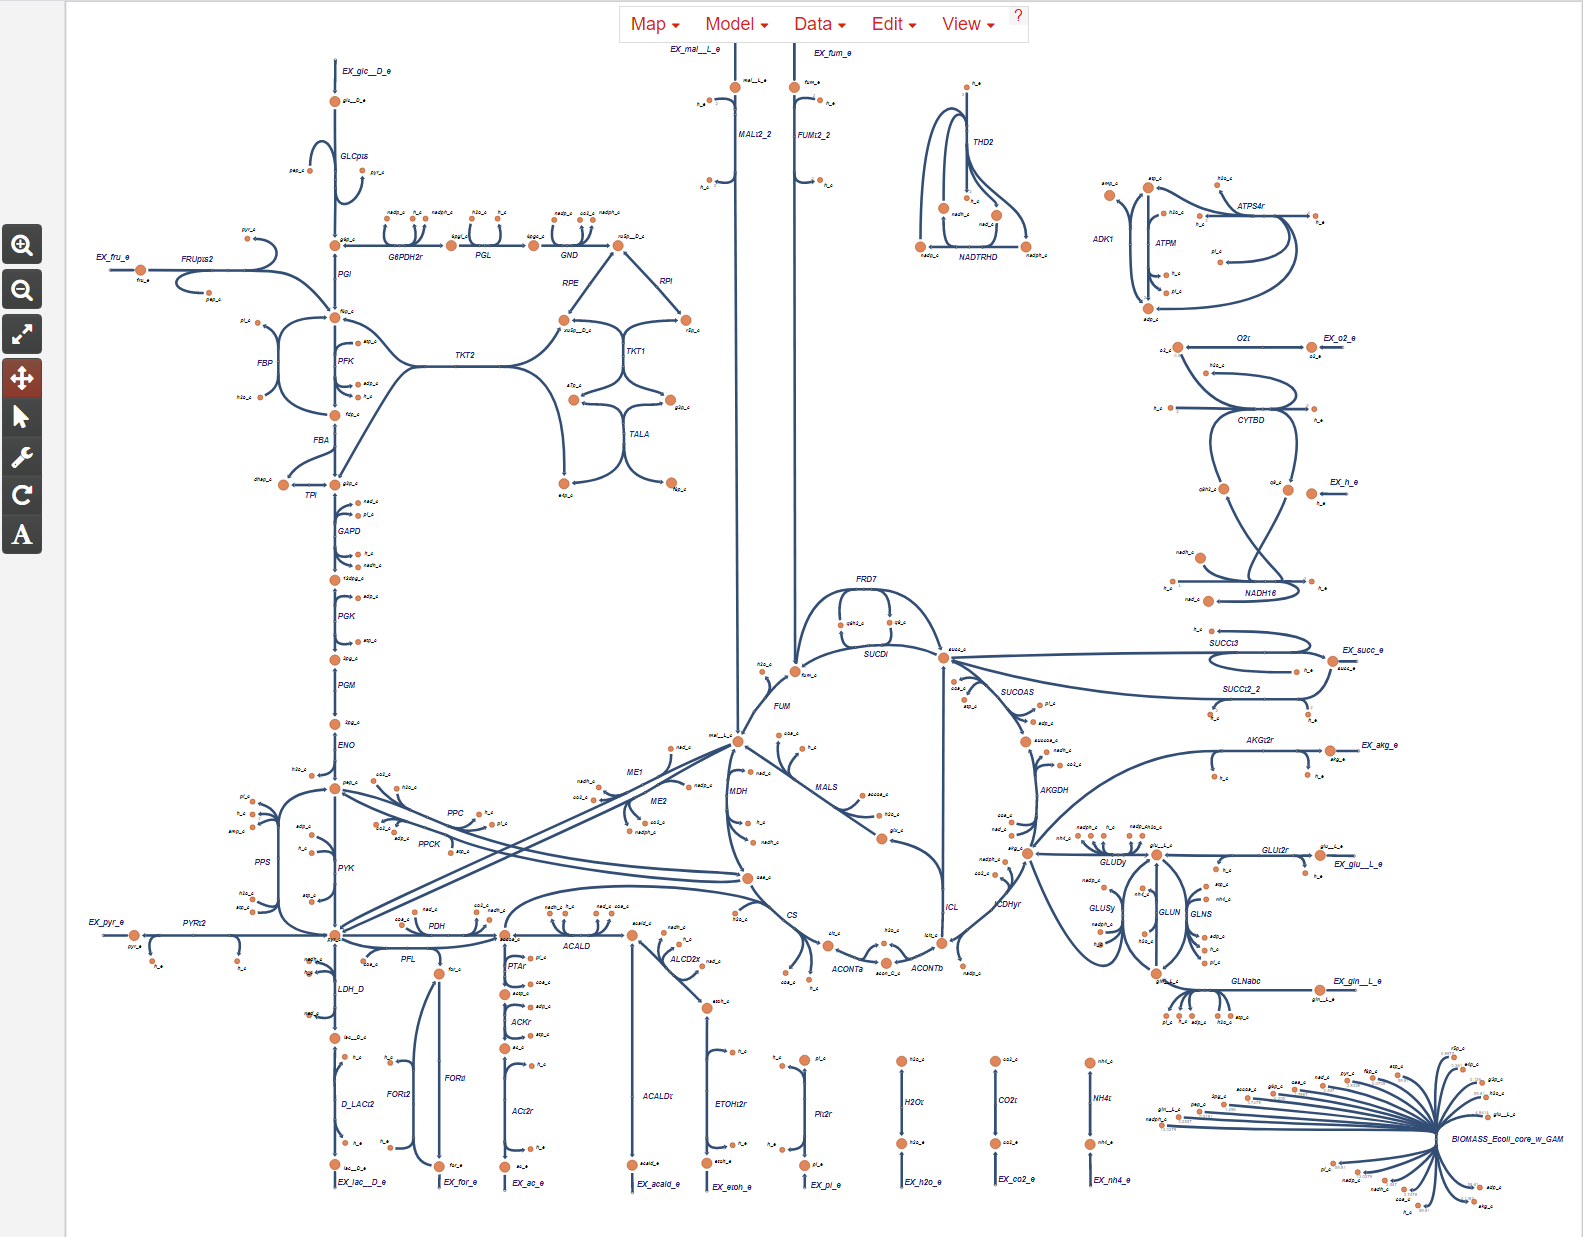

Under the "Data" label on the top of the map click the choice "Load reaction map." A window should open asking for the name of the reaction data file, go to the appropriate directory and enter "escher_flux.csv". The map should then redraw to look like